# Интерполяция. Сплайны

## Пример (мотивация использовать сплайны)

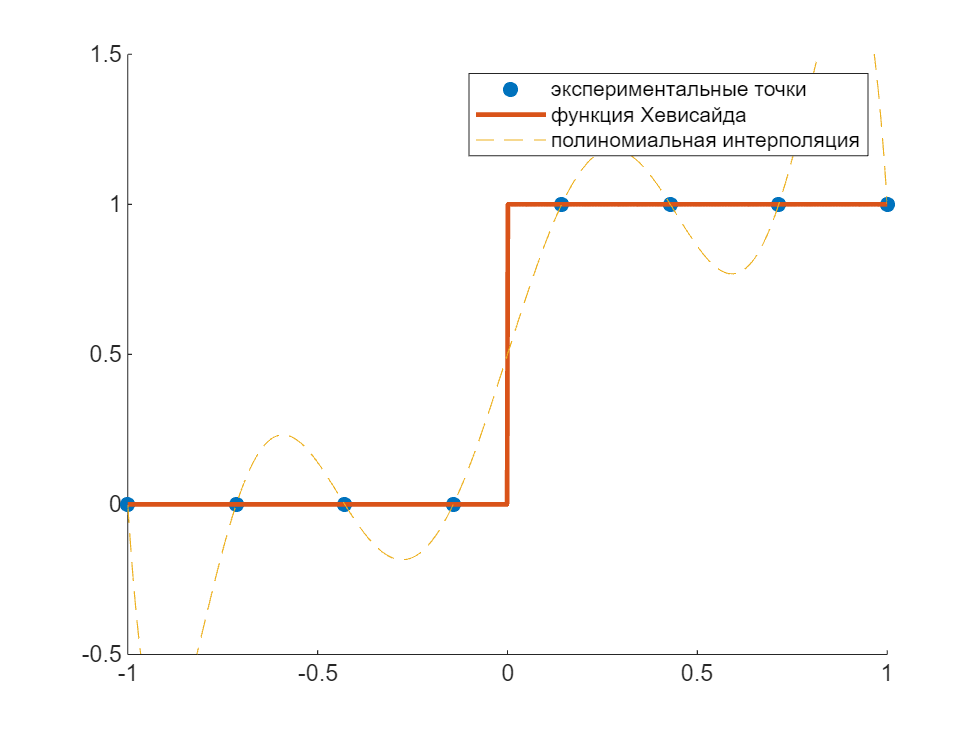

N = 8; % меняем количество "экспериментальных точек"
x = linspace(-1,1,N);
y = heaviside(x);

%полиномиальная интерполяция
p = polyfit(x,y,N-1); % коэффициенты полиномов
yp = polyval(p,linspace(-1,1,1000)); % значение интерполяции


% Рисуем графики
scatter(x,y, DisplayName="экспериментальные точки", MarkerFaceColor="flat")
hold on
plot(linspace(-1,1,1000), heaviside(linspace(-1,1,1000)),DisplayName="функция Хевисайда", LineWidth=2)
plot(linspace(-1,1,1000), yp, DisplayName="полиномиальная интерполяция", LineStyle="--")
legend
ylim([-0.5,1.5])
hold off

## Линейные сплайны

Для n экспериментальных точек $(i = 1, 2, 3, ..., n)$ у нас будет иметься $(n-1)$ интервалов. У каждого интервала будет своя функция $s_i(x)$. Если мы имеем дело с линейными сплайнами, то функция 


$$s_i(x) = a_i+b_i(x-x_i)$$


коэффициенты $a_i = f_i$ (пересечение)

коэффициенты $b_i = \frac{f_{i+1}-f_i}{x_{i+1}-x_i}$ (пересечение)

следовательно вид функции будет выглядеть следующим образом 


$$s_i(x) = a_i+b_i(x-x_i) = f_i+\frac{f_{i+1}-f_i}{x_{i+1}-x_i}(x-x_i)$$


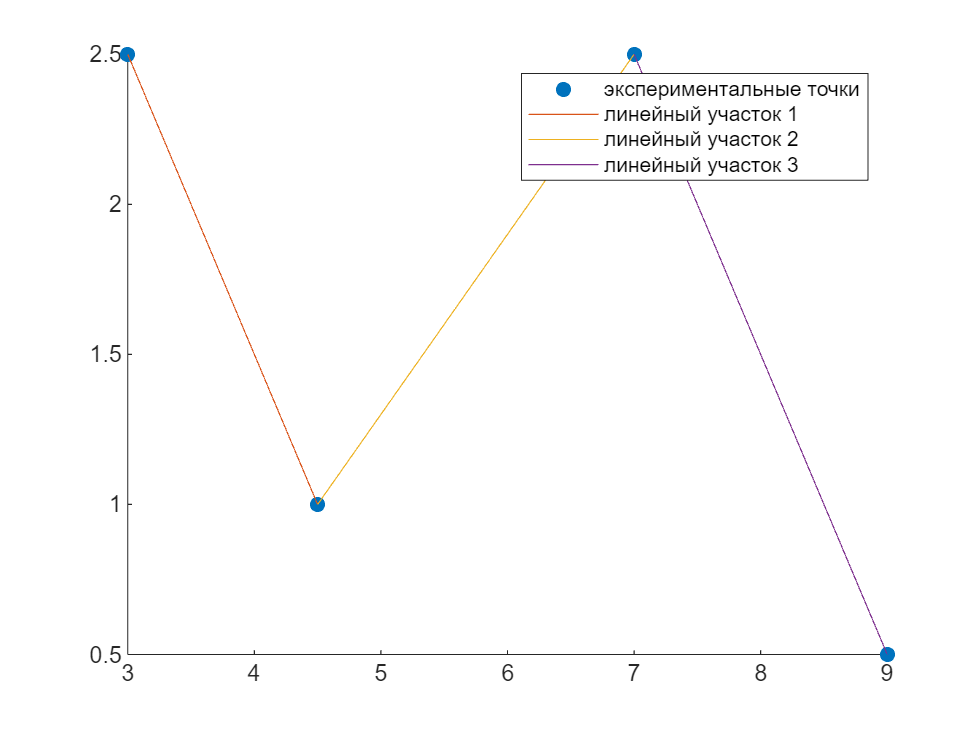

% пример реализации линейных сплайнов
clearvars;
x = [3, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];

xp1 = linspace(3,4.5,100);
xp2 = linspace(4.5,7,100);
xp3 = linspace(7.0,9,100);

%построим s_i(x)
s1 = @(xp) y(1)+(y(2)-y(1))/(x(2)-x(1))*(xp-x(1));
s2 = @(xp) y(2)+(y(3)-y(2))/(x(3)-x(2))*(xp-x(2));
s3 = @(xp) y(3)+(y(4)-y(3))/(x(4)-x(3))*(xp-x(3));

%Нарисуем графики
scatter(x,y, MarkerFaceColor="flat", DisplayName="экспериментальные точки")
hold on
plot(xp1,s1(xp1), DisplayName="линейный участок 1")
plot(xp2,s2(xp2), DisplayName="линейный участок 2")
plot(xp3,s3(xp3), DisplayName="линейный участок 3")
legend
hold off

Минусы линейных сплайнов состоит в том, что итоговый сплайн не является гладким. 

## Квадратичные и кубические сплайны

Для простоты рассмотрим уравнения для квадратичных сплайнов

функция для интервала будет выглядеть следующим образом 


$$s_i(x) = a_i+b_i(x-x_i)+c_i(x-x_i)^2$$


найдем коэффициенты. 

Для n экспериментальных точек $(i = 1,2,3,...n)$ у нас $n-1$ интервал и $3(n-1) $ коэффициентов (a,b,c). То есть нам надо составить $3(n-1) $ уравнений

- функция должна проходить через все точки (условие непрерывности)


$$f_i = a_i +b_i(x_i-x_i)+c_i(x_i-x_i)^2 = a_i$$



$$a_i = f_i$$


Итого мы нашли $(n-1) $ уравнений. Осталось $2(n-1) $

- значения соседних функций должны быть равны в узлах


$$f_i+b_i(x_{i+1}-x_i)+c_i(x_{i+1}-x_i)^2 = f_{i+1}+b_{i+1}(x_{i+1}-x_{i+1})+c_{i+1}(x_{i+1}-x_{i+1})^2 $$


определим шаг $h_i = x_{i+1}-x_{i}$

перепишем и получим


$$f_i+b_ih_i+c_ih_i^2= f_{i+1}$$


таких уравнений мы можем составить $n-1
$ штук. Значит нам остается составить $(n-1) $ уравнений

- Первые производные должны быть на внутренних узлах должны быть одинаковы. Это важное условие для того, чтобы соседние сплайны объединялись гладким образом. 


$$s_i ' = b_i+2c_i(x-x_i)$$


По аналогии мы должны составить уравнения для соседних нод i и i+1


$$b_i+2c_ih_i = b_{i+1}$$


Таких условий у нас $(n-2) $. То есть остается у нас $n-1-(n-2) = n-1+n+2 = 1$. Одно условие

- Предположим, что вторая производная в первой точке равна нулю, получим


$$s_i'' = 2c_i $$



$$s_1'' = 2c_1 = 0 \Rightarrow c_1 = 0$$


Мы определили уравнения для всех коэффициентов. 

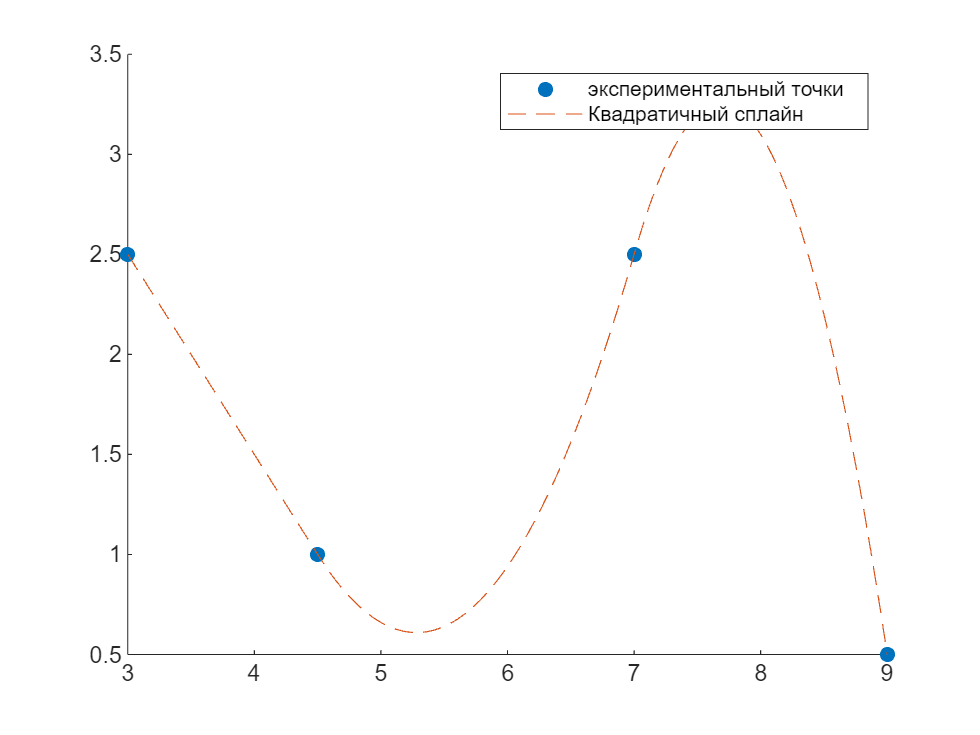

clearvars

x = [3, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];
[coeffs, xplot, yplot] = spline2a(x,y);

scatter(x,y, MarkerFaceColor="flat", DisplayName="экспериментальный точки")
hold on
plot(xplot,yplot, LineStyle="--", DisplayName="Квадратичный сплайн")
legend
hold off

Квадратичные сплайны не так часто используются по разным причинам. Одна из них это возможные осциляции как при интерполяции полиномами высокой степени. Кубические сплайны во многом лучше, хоть и имеют особенности реализации

Для кубического сплайна все тоже самое, просто немного сложнее

Наше уравнение 


$$s_i(x) = a_i+b_i(x-x_i)+c_i(x-x_i)^2+d_i(x-x_i)^3$$


У нас также n экспериментальных точек $(i =1,2,...n)$. Число интервалов $n-1$. Число уравнений, чтобы найти все коэффициенты $4(n-1)$

Условия для кубического сплайна

Первое условие аналогично квадратичным сплайнам 

- функция должна проходить через все точки (условие непрерывности)


$$f(x_i) = a_i+b_i(x_i-x_i)+c_i(x_i-x_i)^2+d_i(x_i-x_i)^3 = a_i$$



$$s_i(x) = f_i+b_i(x-x_i)+c_i(x-x_i)^2+d_i(x-x_i)^3$$


Остается составить 3(n-1) уравнений

- значения соседних функций должны быть равны в узлах


$$f_i+b_ih_i+c_ih_i^2+d_ih_i^3=f_{i+1}$$


где $h_i = x_{i+1}-x_i$

-  Первые производные должны быть на внутренних узлах должны быть одинаковы. Это важное условие для того, чтобы соседние сплайны объединялись гладким образом. $s_i' (x) = b_i+2c_i(x-x_i)+3d_i(x-x_i)^3$ первая производная

равенство производных для двух интервалов в одном узле запишем так:


$$b_i+2c_ih_i+3d_ih_i^2 = b_{i+1}$$


- Вторые производные в узлах должны быть тоже равны 

$s_i''(x) = 2c_i+6d(x-x_i)$ вторая производная

равенство производных для двух интервалов в одном узле запишем так:


$$c_i+3d_ih_i = c_{i+1}$$


отсюда найдем $d_i$


$$d_i = \frac{c_{i+1}-c_i}{3h_i}$$


Путем подстановок можно получить следующее уравнение 


$$h_{i-1}c_{i-1}+2(h_{i-1}+h_i)c_i+h_ic_{i+1}= 3(f[x_{i+1},x_i]-f[x_i,x_{i-1}])$$


Последнее уравнение может быть записано для внутренних узлов, $i = 1,2,3, ..., n-2$  и можно найти коэффициенты $c_1,c_2,c_3...c_{n-1}$ 

Если у нас имеется еще **2 дополнительных условия**, то мы найдем остальные коэффициенты $c$. Дальше мы найдем коэффиенты b и d 

Выбор этих двух условий может быть различным и результирующий сплайн тоже будет различным 

### Сравнение линейного квадратичного и кубического сплайнов

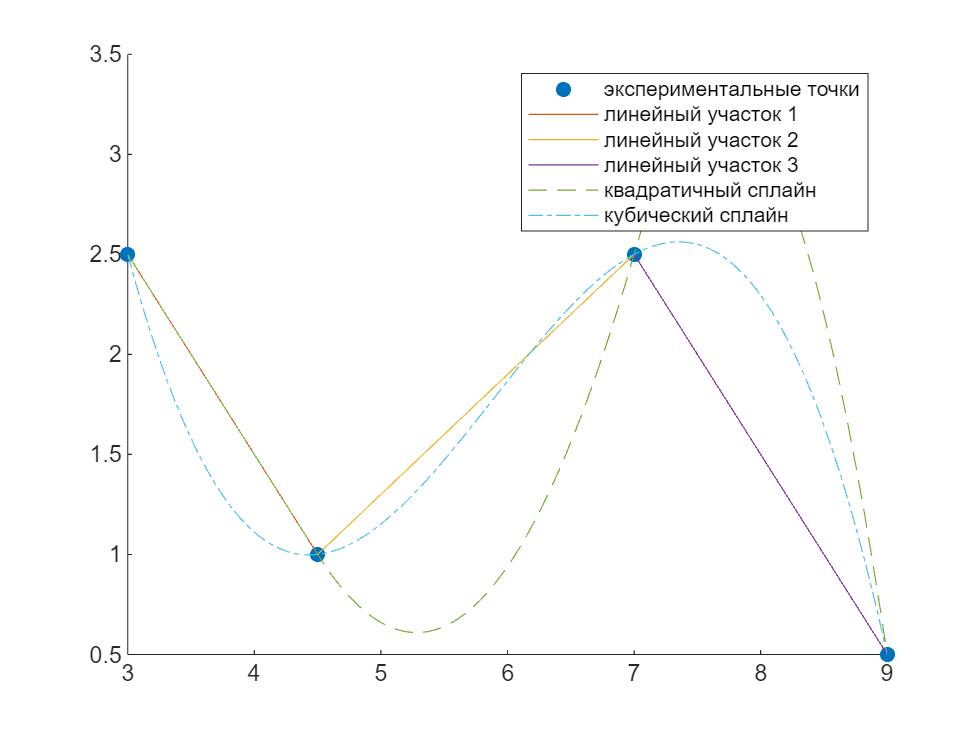

clearvars;
%Начальные точки 
x = [3, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];

%линейные сплайны
xp1 = linspace(3,4.5,100); %интервал 1
xp2 = linspace(4.5,7,100); %интервал 2
xp3 = linspace(7.0,9,100); %интервал 3

%построим s_i(x)
s1 = @(xp) y(1)+(y(2)-y(1))/(x(2)-x(1))*(xp-x(1));
s2 = @(xp) y(2)+(y(3)-y(2))/(x(3)-x(2))*(xp-x(2));
s3 = @(xp) y(3)+(y(4)-y(3))/(x(4)-x(3))*(xp-x(3));

%Квадратичные сплайны
[coeffs, xplot, yplot] = spline2a(x,y);

%кубические сплайны
xx = linspace(x(1),x(end),100);
yy = spline(x,y, xx);


%Нарисуем графики

%Линейные сплайны
scatter(x,y, MarkerFaceColor="flat", DisplayName="экспериментальные точки")
hold on
plot(xp1,s1(xp1), DisplayName="линейный участок 1")
plot(xp2,s2(xp2), DisplayName="линейный участок 2")
plot(xp3,s3(xp3), DisplayName="линейный участок 3")

%квадратичный сплайн
plot(xplot,yplot, LineStyle="--", DisplayName="квадратичный сплайн")
%кубический сплайн
plot(xx,yy, LineStyle="-.", DisplayName="кубический сплайн")

legend
hold off

### Сравнение кубических сплайнов

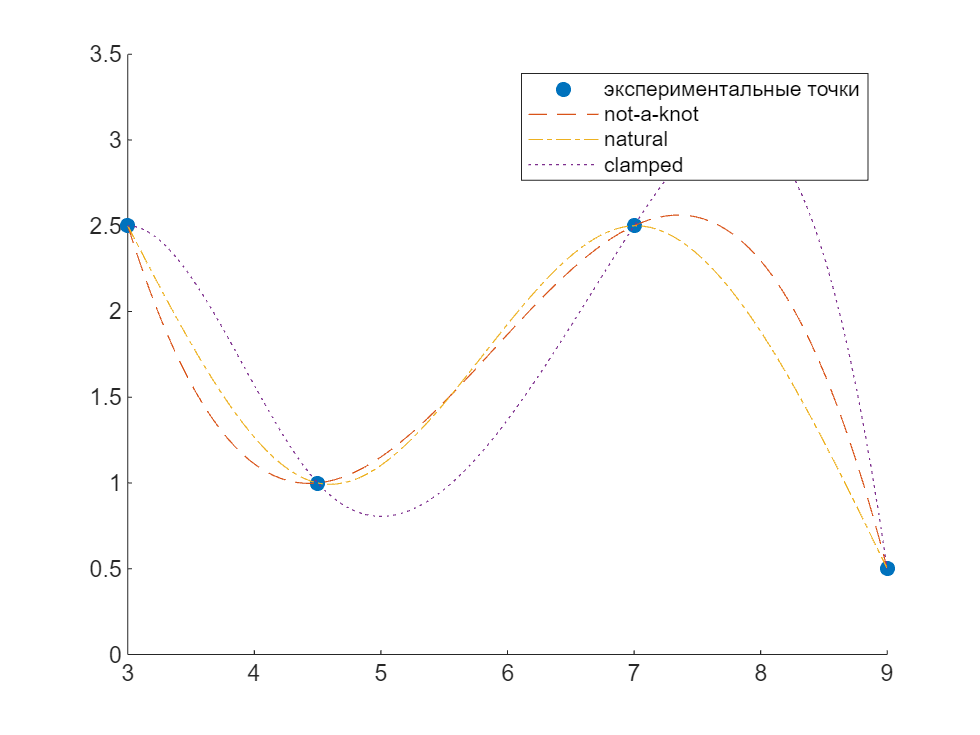

clearvars;
%Начальные точки 
x = [3, 4.5, 7.0, 9.0];
y = [2.5, 1.0, 2.5, 0.5];
xx = linspace(x(1),x(end),100);

scatter(x,y, MarkerFaceColor="flat", DisplayName="экспериментальные точки")
hold on

%not a knot
yy_knot = spline(x,y, xx);
plot(xx,yy_knot, DisplayName="not-a-knot", LineStyle="--")

pp = csape(x,y, "variational");
yy_natural = fnval(pp,xx);
plot(xx,yy_natural, DisplayName="natural", LineStyle="-.")

% clamped
x = [3, 4.5, 7.0, 9.0];
y = [0, 2.5, 1.0, 2.5, 0.5, -5]; % Принимаются во внимание дополнительные точки 
yy_clamped = spline(x,y, xx);
plot(xx,yy_clamped, DisplayName="clamped", LineStyle=":")
legend
hold off

## Многомерная интерполяция

#### билинейная интерполяциия

В двумерном случае у нас есть функция $z = (x_i,y_i)$ 

Мы хотим найти промежуточные значения функции, зная известные точки (узлы)

Допустим нам известны 4 точки x и соотвтествующие значения функции x:$f(x_1,y_1), f(x_2,y_1), f(x_2,y_1),f(x_2,y_2)$

Суть заключается в том, чтобы сначала "пройтись по иксам" (линейная интерполяция вдоль направления x), а затем полученные значения использовать для направления y и в конечном счете можно получить итоговую функцию 

Запишем уравнения используя форму Лагранжа

$f(x_i,y_1) = \frac{x_i-x_2}{x_1-x_2}f(x_1,y_1)+\frac{x_i-x_1}{x_2-x_1}f(x_2,y_1)$  уравнение для $(x_i,y_1)$

$f(x_i,y_1) = \frac{x_i-x_2}{x_1-x_2}f(x_1,y_2)+\frac{x_i-x_1}{x_2-x_1}f(x_2,y_2)$  уравнение для $(x_i,y_2)$

Эти точки используем для линейной интерполяции вдоль y, чтобы получить финальный результат 


$$f(x_i,y_i) = \frac{y_i-y_2}{y_1-y_2}f(x_i,y_1)+ \frac{y_i-y_1}{y_2-y_1}f(x_i,y_2)$$


Итоговое уравнение 


$$f(x_i,y_i) = \frac{x_i-x_2}{x_1-x_2}\frac{y_i-y_2}{y_1-y_2}f(x_1,y_1) +

\frac{x_i-x_1}{x_2-x_1}\frac{y_i-y_2}{y_1-y_2}f(x_1,y_1) +

\frac{x_i-x_2}{x_1-x_2}\frac{y_i-y_1}{y_2-y_1}f(x_1,y_2)+

\frac{x_i-x_1}{x_1-x_2}\frac{y_i-y_1}{y_2-y_1}f(x_2,y_2)$$


## Использование готовых функций для интерполяции

#### функция spline

Cubic spline data interpolation. (только кубическая интерполяция)

два "режима" работы 

мы можем передать либо 2 либо 3 аргумента

- Мы можем передать 3 аргумента (известное значение **х**, известное значение **y**, **новое **значение** x**). В качестве известных значений необходимо передать вектора. В качестве нового значения можно передать конкретную точку, для расчета функции в этой точке, либо передать вектор, и результат работы функции будет вектор новых значений y

- Мы можем передать 2 аргумента (известное значение **х**, известное значение **y**). Результатом работы функции будет некая структура структура. Получить данные y из этой структуры можно с помощью функции fnval(pp,xx) (pp это наша структура)

Также, если length(y)>length(x) на 2 то тогда будут применяться clamped condition. Если вектора равной длины, то not-a-knot condition

Также существуют другие способы кубической интерполяции.

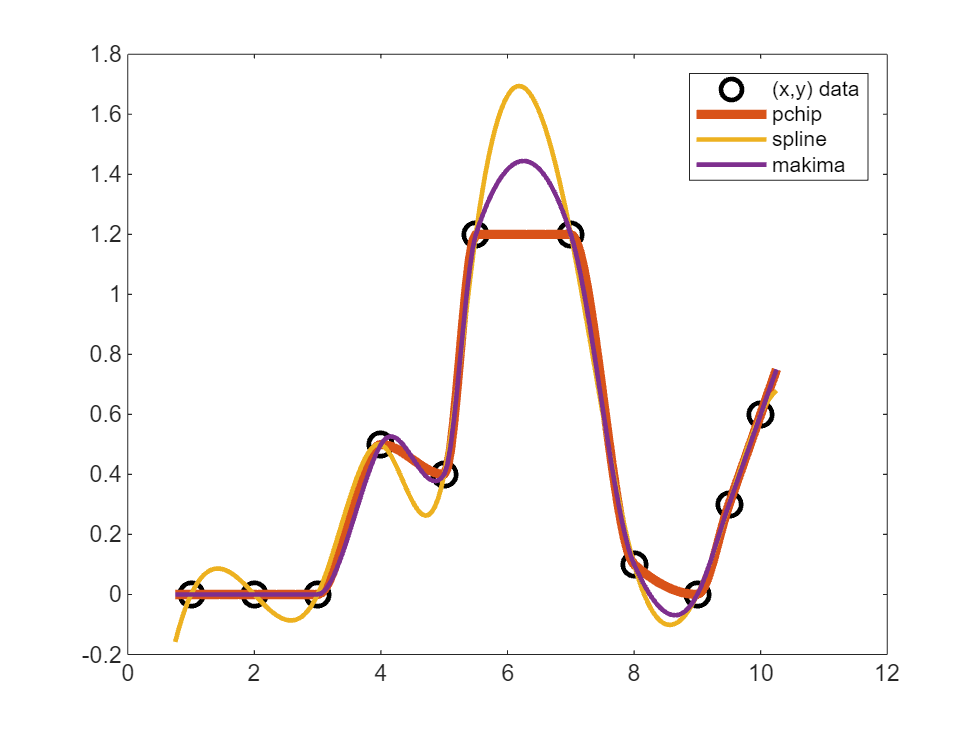

%Пример из хелпа
clearvars
x = [1 2 3 4 5 5.5 7 8 9 9.5 10];
y = [0 0 0 0.5 0.4 1.2 1.2 0.1 0 0.3 0.6];
xq = 0.75:0.05:10.25;
yqs = spline(x,y,xq);
yqp = pchip(x,y,xq);
yqm = makima(x,y,xq);

plot(x,y,'ko','LineWidth',2,'MarkerSize',10)
hold on
plot(xq,yqp,'LineWidth',4)
plot(xq,yqs,xq,yqm,'LineWidth',2)
legend('(x,y) data','pchip','spline','makima')
hold off

Если функция spline (makima pchip) по сути разные варианты кубической интерполяции, то функция interp1 позволяет провести интерполяцию и другими функциями 